Name: Saikrishna Saketh Y

Student Number: 723400

***BER is observed to be 0 for 50% of the Simulation***

**The values N1 and N2 apart from lecture slide perspective is chosen to be**

1, The paradigm of Lagrangian time interpolation is used to implement, it is done using Pk(alpha),

we have the implementation equation in lecture slide 17.

Now that N1 = N2 = 1, Nextly I analytically calculated the expresssion P-1(alpha), P0(alpha) and P1(alpha),

Their coefficients are fed in form of matrix, like below

m = [ ptr^2*[0.5 -1 0.5]; ptr*[-0.5 0 0.5]; [0 1 0]];

Then the product of matrix and samples is considered to be product vector, then sum of the product vector be the output of the filter.

Selection Parameters of Fo, Fb, and Fs are chosen according to the underlying instructions, I chose Fo, which is strictly less than **15Khz**

**Considering Kt = 1, and Kp and Ki is selected based on Design equations, thetaN is considered as pi/100, thus Kp and Ki are calculated to achiece BER much lesser than 0.5**

**(**Various iterations tried to ensure better BER and eye diagram)

Binary phase-shift keying + pulse shaping + FM transmitter and timing error detection using Farrow interpolating filters and RTL-SDR 

By R.W.

clear all, close all

% addpath ../funcs
% ==================================================================
%Script to set parameters
%rw_fmrx_init

% File to dump the output signal
fnam = 'bpsk_signal.wav';

% Parameters to choose:
%
% Frequency of the information bits to send.

Fs = 120e3;
Fo = 12e3;
Fb = 3e3;
N1F = 1;
N2F = 1;
KT = 1;
KP = 0.118;
KI = 0.003;
% % Sampling rate of the FM modulator's input signal. 
% Note that the FM bandwidth is 15 KHz
% Fs
% Over-sampling factor in the audio file is therefore Fs/Fo
%
% Coefficients of the loop filter and the gain of the timing error
% detection
% KP, KI, KT
%
% Implement pulse shaping filter rw_pulse_shaping 
% Implement FM demodulator rw_fmrx
% Implement decimation to audio sampling rate rw_dec_audio
% Implement matched filter for the transmitted pulse rw_matched_pulse
% Implement Farrow filter rw_farrow
% Implement early-late timing error detection rw_el_ted
% Implement counter for the control loop rw_mod_counter
% Implement matched filter for the preamble rw_matched_preamble
% Implement estimator of the noise power noise_pow_est
% 
% Except rw_fmrx, rw_lf_ted these are on-line anonymous functions


% Preamble: Maximum length sequence
pnseq=comm.PNSequence('Polynomial',[5 2 0],'SamplesPerFrame',31,...
    'InitialConditions',[0 0 0 0 1]);
pn31 = sign(pnseq()' -0.5);
preamble = pn31;

% Typically the overhead from control signaling in wireless sytems is 10-20%
% Here preamble is the only control signal (no channel estimation, power
% control command, system information...) so the overhead can be smaller.
% It's arbitrary in this exercise anyway.
% #Information bits/message
Nbit = 300-length(preamble);
% Sets the seed for the random generator so that the message is always the
% same
rng(2308975234);
% Message consists of +- ones
msg = sign(randn(1,Nbit));

% A slot consists of the header and the payload
slot = [preamble,msg]; 
% A frame consists of Nslot slots
Nslot = 12;
frame = kron(ones(1,Nslot), slot);

% Make msg a column vector for the compatibility of dimensions
%msg = msg(:);

% front-end sampling rate, 
FESR = 240e3;
% #Slots to read over wireless, more than 1. This way there is at least one
% complete slot in one vector read by the dongle
Nradslot = 4;
Nsample = Nradslot*FESR/Fo*length(slot);
% #Output vectors to read from the dongle
Nloop = 100;

% ===========================================================================

## Part 1: Make the signal to transmit

Make a wav file that is then used as input to FM transmitter DBPSK odulation and shaping. Sine wave signals bit 1 Information signal for FM modulation at sampling frequency Fs

bpsk_signal = rw_pulse_shaping(frame,Fs/Fo);

% It's necessary to normalize the range [-1,1] for audiowrite
bpsk_signal = bpsk_signal/max(abs(bpsk_signal));

## Write the frame into audio file

This file is then transmitted with the FM transmitter Dongle has 8-bit analog-to-digital converter, so use the same number here

audiowrite(fnam,[bpsk_signal,bpsk_signal,bpsk_signal,bpsk_signal,bpsk_signal,bpsk_signal,bpsk_signal],Fs,'BitsPerSample',8,...
	'Title','BPSK signal','Artist','RW','Comment',date)
audioinfo(fnam)

ans = struct with fields:
             Filename: 'F:\Aalto\Course_Work_&_Modules\Period I-II 2018\Signal_Processing_for_Comm\Code\E5410-master\matlab\task10\bpsk_signal.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 120000
         TotalSamples: 36400
             Duration: 0.3033
                Title: 'BPSK signal'
              Comment: '16-Dec-2018'
               Artist: 'RW'
        BitsPerSample: 8



% The way to run audio in Ubuntu with Alsa 
%system('speaker-test -r sampling-rate -l 0 -t wav -W . -w fm_data.wav')
% 
% In /bin/bash
% while :; do afplay -r sampling-rate fm_data.wav; done
%
% Quicktime in Mac, Mediaplayer in Windows
% In Windows we play
%powershell -c (New-Object Media.SoundPlayer "c:\PathTo\YourSound.wav").PlaySync();
%
% Or upload to a phone and transmit
%
% Put your system to transmit until you move on to the receiver part


% ============================================================================

## Part 2: Receive

Radio parameters. Find an empty channel without any FM station

expFreq = 89.5e6;

hSDRrRx = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency',     expFreq, ...
    'EnableTunerAGC',      true, ...
    'SampleRate',          FESR, ...
    'SamplesPerFrame',     Nsample, ...
    'FrequencyCorrection', 40, ...
    'OutputDataType',      'double');

hSpectrumAnalyzer = dsp.SpectrumAnalyzer(...
    'Name',             'Actual Frequency Offset',...
    'Title',            'Actual Frequency Offset', ...
    'SpectrumType',     'Power density',...
    'FrequencySpan',    'Full', ...
    'SampleRate',       FESR, ...
    'YLimits',          [-60,10],...
    'SpectralAverages', 10, ...
    'FrequencySpan',    'Start and stop frequencies', ...
    'StartFrequency',   -50e3, ...
    'StopFrequency',    50e3,...
    'Position',         figposition([50 30 30 40]));

## Rx loop

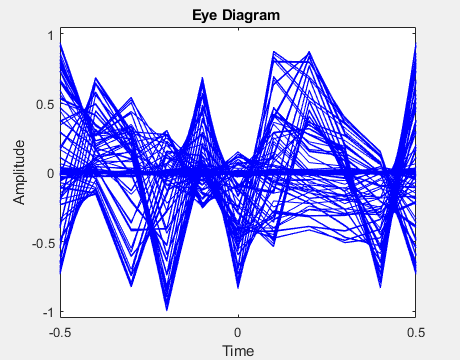

if isempty(sdrinfo(hSDRrRx.RadioAddress))
    warning(message('SDR:sysobjdemos:MainLoop'))
    return
end

% Allocate memory for signal storage
%rxSigStore = zeros(1,Nsample*Nloop);
ber_vec = ones(1,Nloop);
% Matched filter output after synchronization
ymf = zeros(1,Nsample*Fo/FESR);
fa = figure('Name','timing accumulator'); 
fb = figure('Name', 'BER');
hb = animatedline('Marker','o');
axis([0 Nloop 0 1]);
% Oversampling factor in the audio file. Must be even
L=Fs/Fo;
% Handle for the eye diagram
heye = eyediagram(bpsk_signal,L);    

% Estimation of the noise power
noise_est = 1;

% Time elapsed
fprintf('Loop time: %f s\n',Nsample*Nloop/FESR)

Loop time: 10.000000 s


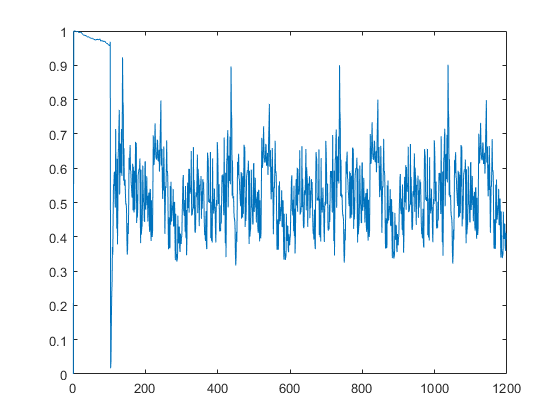

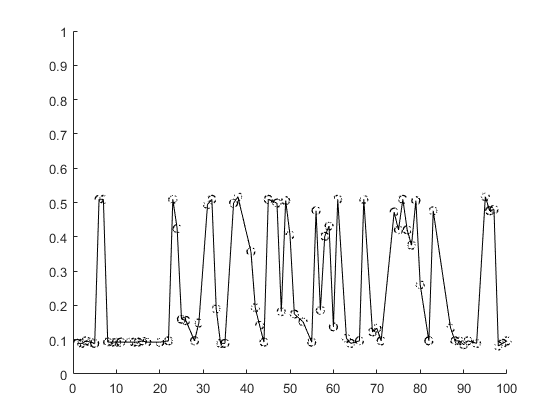

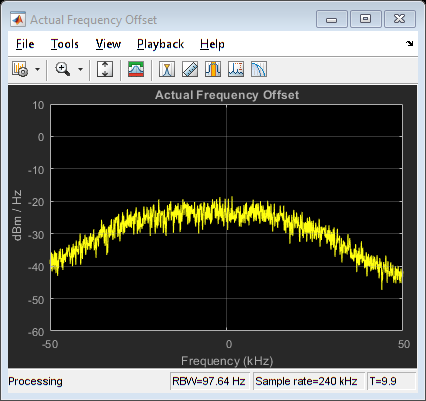

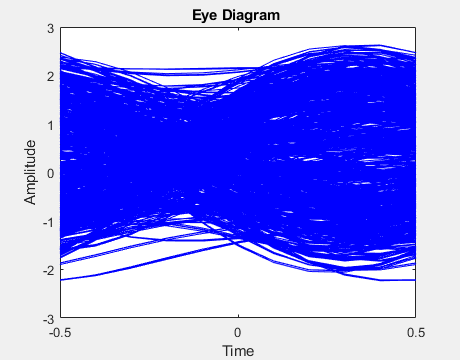

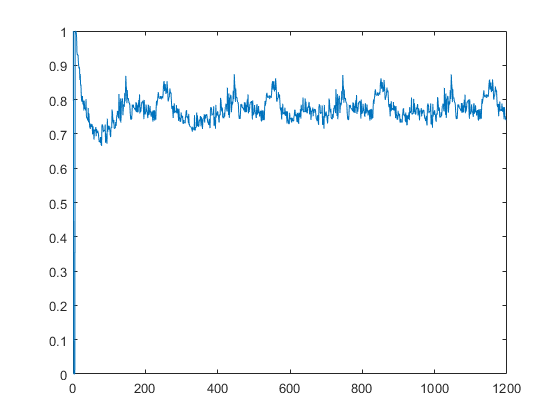

tstart = tic;
for ii = 1:Nloop
    [rxSig, ~] = step(hSDRrRx);
    rxSig = rxSig - mean(rxSig);  % Remove DC component
        
    % Display received frequency spectrum
    hSpectrumAnalyzer(rxSig);
    
    %rxSigStore((iFrame-1)*SPF+[1:SPF]) = rxSig;
    % FM demodulator using discriminator
    rd = rw_fmrx(rxSig,FESR);
 
    % Decimate to audio sampling rate first
    rd_audio = rw_dec_audio(rd,FESR/Fs);
 
    % Matched filtering and derivative MF of the pulse shaping filter
    after_mf = rw_matched_pulse(rd_audio,Fs/Fo); 
    % Doown-sample to 2x sampling rate w.r..t. bit rate
    % No aliasing, because the signal is band-limited to (1+r)*bit-rate, r
    % is the roll-off factor
    % It would have been possible to filter with a matched filter  with
    % oversampling factor 2. Now the #samples/symbol in the MF is L
    after_mf_down = after_mf(1:L/2:end);
    
    % Option to check that the Tx-Rx chain works without over-the air transmission
    % Note that the length is not the same as length(rd_audio)
    % Comment out when it works
    %after_mf = rw_matched_pulse(bpsk_signal(:));
    % Plot to the same eye diagram using figure handle heye
    eyediagram(after_mf,L,1,0,'b-',heye);
    
    % Search for the timing
	ptr = 0; v_accu=zeros(1,Nbit);  lstate=0;
	% Symbol clock, 2 times slower than MF output rate
	kk = 0;
	for jj = 2+N1F:2:length(after_mf_down)-(N2F+2)
  
		kk = kk+1;
		% Interpolation using Farrow filter
        % Set the indices N1F and N2F and calculate the Farrow filter
        % coefficients accordingly
        ymf(kk) = rw_farrow(after_mf_down(jj-N1F:jj+N2F), ptr);
        early = rw_farrow(after_mf_down(jj-N1F-1:jj+N2F-1), ptr);
        late = rw_farrow(after_mf_down(jj-N1F+1:jj+N2F+1), ptr);
		% early-late timing error detector
		err = KT*rw_el_ted(ymf(kk)/noise_est,early,late);
 	
        % 1st order loop filter function
        % Input: loop filter coefficients, instantaneous error, internal
        % state
		[t_err, lstate] = rw_lf_ted(KP,KI,err,lstate);

        % Counter to control the sampling.
		% Update accumulator with the filtered timing error such 
        % that it stays in the range [0,1]
        ptr = rw_mod_counter(t_err, ptr, 1);
 		v_accu(kk) = ptr;
	end  % Timing loop
 
    % Check the performance of the timing loop
    % Comment out if the loop slows down
	figure(fa), plot(v_accu), drawnow limitrate
    
    % Find the preamble using the  preamble sequence
    % Phase can be flipped so use abs()
    after_premf = rw_matched_preamble(ymf,preamble);
    [~, idx] = max(abs(after_premf));
    
    % Channel phase estimation
    if after_premf(idx)<0, ymf = -ymf; end
    
    % If the index is too large so that the slot cannot start here,
    % don't attempt to decode and go read a new sample vector
    if idx+Nbit > Nradslot*Nbit, continue,  end

    % Index OK, decode
    msgd = sign(ymf(idx+[1:Nbit]));  

    % Estimate the noise standard deviation from the preamble. 
    % Output of the MF vector needs to be multiplied by the preamble to
    % undo data modulation
    % The operation signals run-time error if idx < length(preamble) but this is not
    % probable. 
    if (idx-length(preamble) >= 0) 
        noise_est = rw_noisepow_est(ymf(idx-length(preamble)+1:idx), noise_est);
    end
    %noise_est = 1;
    % Bit-error rate
    ber_vec(ii) = sum(msg~=msgd)/Nbit;
    %fprintf('Bit error rate %f at round %d\n', ber_vec(ii), ii)
    % Plot BER point by point. Comment out if too slow
    addpoints(hb, ii, ber_vec(ii)), drawnow limitrate
end

fprintf('Elapsed time %f s\n', toc(tstart))

Elapsed time 53.222678 s


    
% Check the bit-error rates
%stem(ber_vec)

## Release all System objects

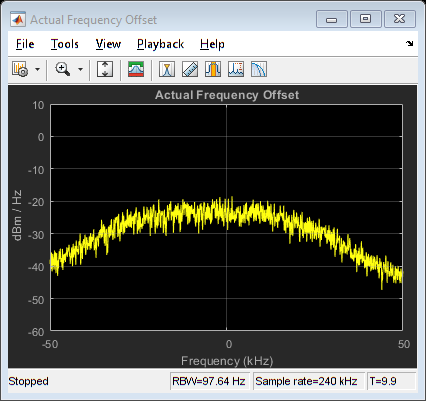

release(hSDRrRx); 
release(hSpectrumAnalyzer)

clear hSDRrRx

function bpsk_signal = rw_pulse_shaping(frame,upsampling)
   %raised_cosine = rcosdesign(0.2,length(frame),upsampling);
   raised_cosine = rcosdesign(1,16,upsampling);
   % dbpsk_signal = filter(raised_cosine,1,frame);
   bpsk_signal = upfirdn(raised_cosine, frame, upsampling, 1);
end

function rd = rw_fmrx(rxSig,FESR)
  %rd = angle(delayseq(rxSig,delay).*conj(rxSig));% using filter
  filterdelay = filter([0 1],1,rxSig);
     
  rd = angle(filterdelay .* conj(rxSig));
  FLOW = fir1(50,15e3/(FESR/2));
  memo = zeros(1, length(FLOW)-1);
  [rd,~]=filter(FLOW,1,rd,memo);
end
function rd_audio = rw_dec_audio(rd,factor)
 rd_audio = decimate(rd,factor);
end

function after_mf = rw_matched_pulse(rd_audio,upsampling)
  raised_cosine = rcosdesign(1,16,upsampling);
  after_mf = filter(raised_cosine,1,rd_audio);
end

function ymf = rw_farrow(after_mf_down,ptr)
%Considering N1=1 and N2=1 from lecture slide perspective.
%ptr is alpha
m = [ ptr^2*[0.5 -1 0.5]; ptr*[-0.5 0 0.5]; [0 1 0]];
ymf = sum(m*after_mf_down);

end
function err = rw_el_ted(y_n,early,late)
     err = tanh(y_n).*(late-early);
end

function [t_err, lstate] = rw_lf_ted(KP,KI,err,lstate)
    t_err = KP*err + KI*err + lstate;
    lstate = KI*err+lstate;
end
function ptr = rw_mod_counter(t_err, ptr, L)
    ptr = mod(t_err+ptr,L);
end

function after_premf = rw_matched_preamble(ymf,preamble)
    after_premf = filter(fliplr(preamble),1,ymf);
end

function noise_est = rw_noisepow_est(ymf, noise_est)
 h = 0.35;
 v = var(ymf);
 noise_est = (h*v) + sqrt(1-h^2)*noise_est;
 
end